# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 6-b. 시스템 유형과 내부 모델 이론 소개**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 단위 계단 응답의 정상상태값과 시스템 응답 간의 관계

이전 예제와 동일하게 다음의 연속 시간 플랜트 


$$G_p(s)=\frac{1}{s+1}$$


를 샘플 데이터 시스템 환경에서 제어하는 문제를 생각합시다.

num_Gp_tf = [1];
den_Gp_tf = [1 1];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);

T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh')

Gd_tf =
 
    0.1813
  ----------
  z - 0.8187
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


이때 위의 펄스 전달함수는 시스템 유형이 0임에 유의합시다. (즉, `Gd_tf` 는 $z=1$을 극점으로 가지지 않습니다.)

따라서 이 시스템만으로 폐루프 시스템을 구현하면, 폐루프 시스템의 정상상태 오차가 0으로 수렴하지 않습니다. 

이를 확인하기 위해 `step` 함수를 이용하여 단위 계단 응답을 얻어봅시다.

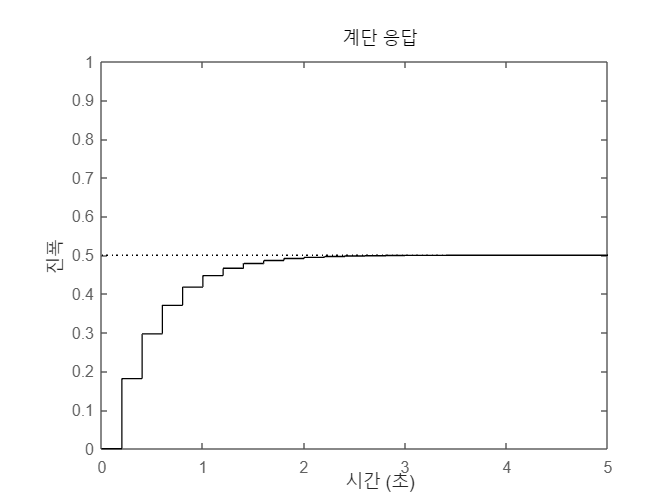

Td_tf_1 = Gd_tf/(1+Gd_tf);
Td_tf_1 = minreal(Td_tf_1);

figure();
step(Td_tf_1, 'k');
xlim([0 5]);
ylim([0 1]);

단위 계단 응답의 구체적인 수렴값은 $0.5$로써, 이는 최종값 정리(final value theorem)을 통해 쉽게 도출할 수 있습니다.

이제 시스템에 제어기를 추가함으로써 시스템 유형을 키우도록 하겠습니다.

이전 예제에서처럼 $z=1$을 극점으로 가지는 다음의 제어기


$$C^d(z) = \frac{3T}{z-1}$$


를 설계합니다.

num_Cd_tf = 3*T;
den_Cd_tf = [1 -1];
Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);

위의 제어기를 추가하여 새롭게 얻은 개루프(open-loop) 전달함수 $L^d(z) = G^d(z)C^d(z)$는 $z=1$에 위치한 하나의 극점이 존재하므로, 시스템 유형이 1이라고 할 수 있습니다.

이제 이 제어기를 추가하여 구성한 폐루프 시스템의 단위 계단 응답을 그려봅시다. 

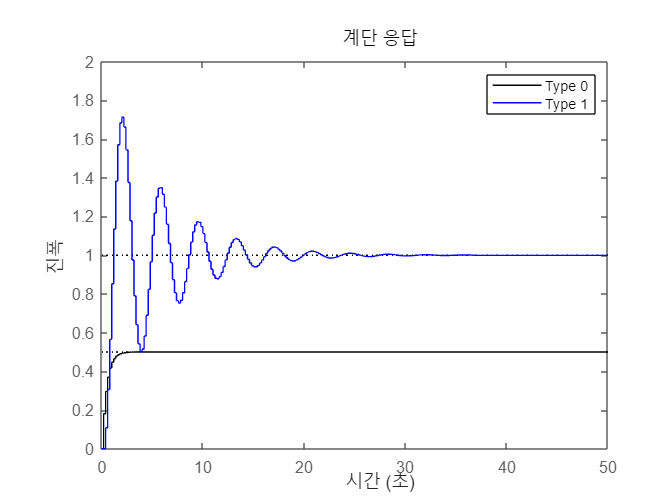

Td_tf_2 = (Gd_tf * Cd_tf)/(1 + Gd_tf * Cd_tf);
Td_tf_2 = minreal(Td_tf_2);

figure();
step(Td_tf_1, 'k');
hold on;
step(Td_tf_2, 'b');
xlim([0 50]);
ylim([0 2]);
legend('Type 0','Type 1');

### Topic 2 : 주파수 응답과 시스템 유형 간의 관계

개루프 전달함수 $L^d(z)$의 정확한 수식을 모른다고 하더라도, 이 전달함수의 주파수 응답의 개형을 통해 시스템의 유형을 유추해볼 수 있습니다. 

만약 개루프 시스템의 유형이 1 이상이라고 하면, $L^d(1) = \infty
$를 만족해야 합니다. 

위의 문장을 주파수 영역에서 다시 해석해보면, $L^d(z)$의 주파수 특성 $L^d(e^{j\omega T})$이 $\omega=0$일 때 무한의 값을 가져야 한다고 결론내릴 수 있습니다. 

이를 확인해보기 위해 앞에서 얻은 두 경우의 예제에 대해, 각각의 개루프 전달함수 $G^d(z)$와 $G^d(z)C^d(z)$의 보데 선도(bode plot)을 그려봅시다. 

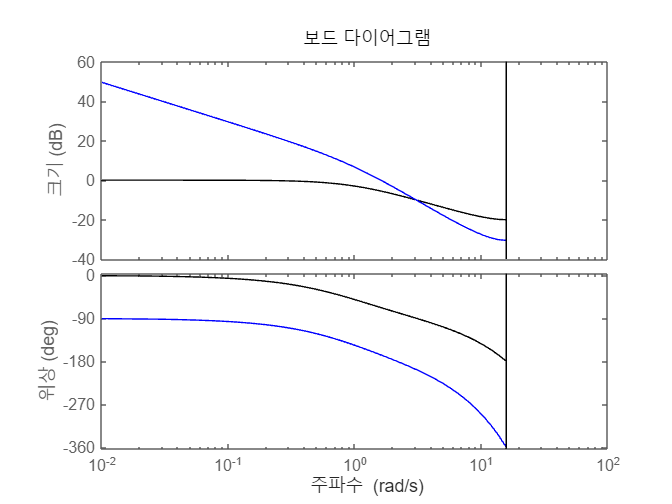

figure();
bode(Gd_tf, 'k');
hold on;
bode(Gd_tf*Cd_tf, 'b');

$G^d(z)C^d(z)$이 $\omega=0$에서 상대적으로 매우 큰 값을 가짐을 확인할 수 있으며, 이를 통해 개루프 시스템의 시스템 유형이 1 이상일 것이라고 짐작해볼 수 있습니다.

각각의 경우에 대해 폐루프 전달함수 $T^d(z) = \frac{L^d(z)}{1+L^d(z)}$의 보데 선도를 통해 위의 현상을 좀 더 자세히 이해할 수 있습니다.

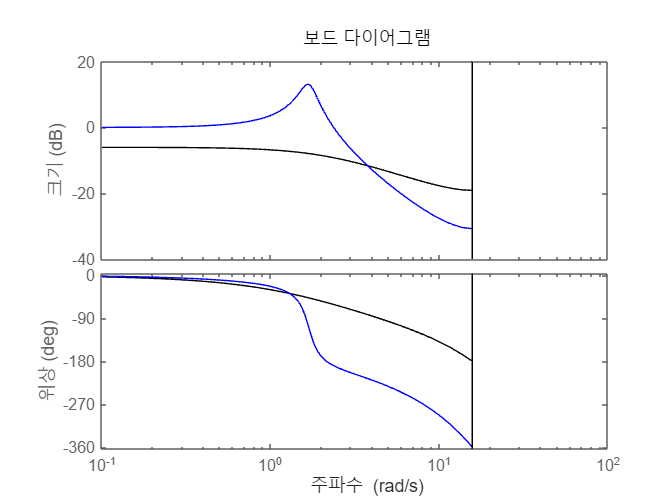

figure();
bode(Td_tf_1, 'k');
hold on;
bode(Td_tf_2, 'b');

### Topic 3 : 내부 모델 이론의 개념적인 이해

시스템 유형이라는 개념은 폐루프 시스템의 입력인 추종 신호 $r^d(k)$가 단위 계단 신호 등의 경우에서, 전체 시스템의 정상상태의 오차가 0이 되도록 하는 조건을 찾기 위해 등장하였습니다. 

하지만 경우에 따라 추종 신호가 단위 계단 신호가 아닌 다음의 정현파(sinusoidal)


$$r^d(k) = A \sin(\omega_0 k T+\theta^d)$$


의 형태로 입력될 수 있습니다. 

앞서 시스템 유형의 상황을 돌이켜볼 때, 위의 추종 신호를 정상상태에서 오차 없이 추종하기 위해서는, 


$$L^d(e^{j\omega T}) = G^d(e^{j\omega T})C^d(e^{j\omega T})=\infty,~~~\text{at}~\omega = \omega_0$$


를 만족해야 할 것이라 예상할 수 있습니다. 우리 예제에서는 $G^d(e^{j\omega_0 T})$는 $\infty$의 값이 아니기 때문에, 필연적으로 이산 시간 제어기 $C^d(e^{j\omega_0 T})$가 무한의 값을 가지도록 제어기가 잘 설계되어야 합니다. 

이를 만족하는 제어기의 예시는 아래와 같습니다.


$$C^d(z)=\frac{K_1 z + K_0}{z^2 - 2 \cos(\omega T)z + 1}$$


여기서 제어기의 분모식인 $z^2 - 2\cos(\omega_0 T)z+1$은, 위의 정현파 추종 신호 $r^d(k)$를 z-변환하였을 때의 분모식과 동일합니다.

따라서 위의 제어기는, 어떤 의미에서는 추종하고자 하는 정현파 신호의 모델을 내부적으로 가지고 있다고도 볼 수 있습니다. 

이렇듯 추종할 신호의 모델을 제어기가 가지고 있을 때 정상상태의 추종 오차가 0이 되는 현상을 내부 모델 이론(internal model principle)이라 부릅니다.

실제로 위의 제어기를 사용하였을 때 정상상태의 추종 오차가 0으로 수렴하는지를, 최종값 정리를 이용하여 증명할 수도 있습니다. 

하지만 여기서는 이를 증명하지는 않고, Simulink 환경에서 위의 제어기를 이용하여 실제 오차가 0으로 수렴하는지를 확인하는 정도로만 진행하려 합니다. 

$\omega_0=0.5$라 가정하며, 이에 대해 제어기의 이득값(gain)이 $K_1=0.1$, $K_0 = -0.09$로 적절히 선정되었다고 합시다.

omega_0 = 0.5;
num_Cd_tf = 0.1*[1 -0.9];
den_Cd_tf = [1 -2*cos(omega_0*T) 1];

Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);

Td_tf = (Gd_tf * Cd_tf)/(1 + Gd_tf * Cd_tf);
Td_tf = minreal(Td_tf);

이제 위의 제어기에 대해 미리 구현된 Simulink 파일을 구동해봅시다.

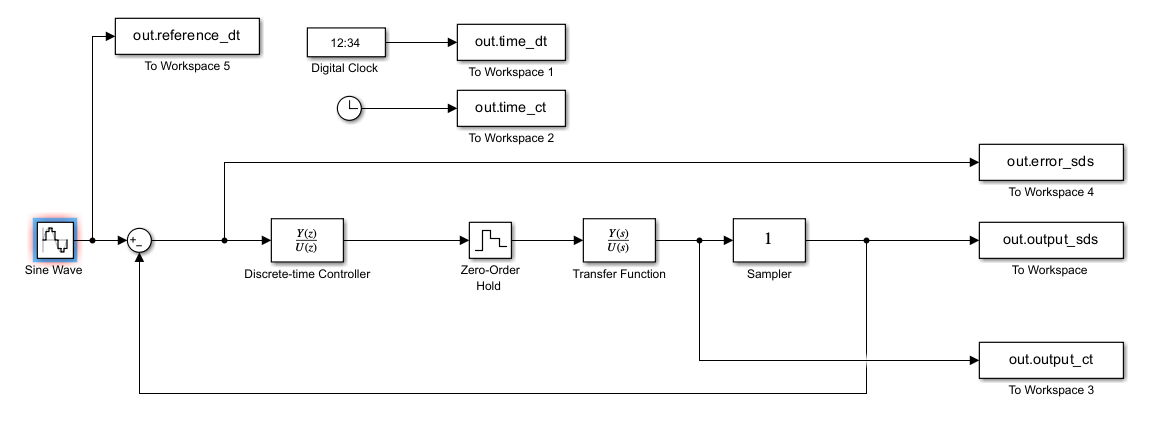

T_sim = 120;
dt_sim = 0.001;             

sim('sim_topic3.slx');
simout = ans;
time_dt_sim3 = simout.time_dt;
time_ct_sim3 = simout.time_ct;
output_ct_sim3 = simout.output_ct;
output_sds_sim3 = simout.output_sds;
error_sds_sim3 = simout.error_sds;
reference_dt_sim3 = simout.reference_dt;

이제 위 시스템의 추종 오차인 $e^d(k) = r^d(k) - y^d(k)$를 시간에 따라 그려보면, 오차가 시간이 지남에 따라 0으로 수렴함을 확인해볼 수 있습니다.

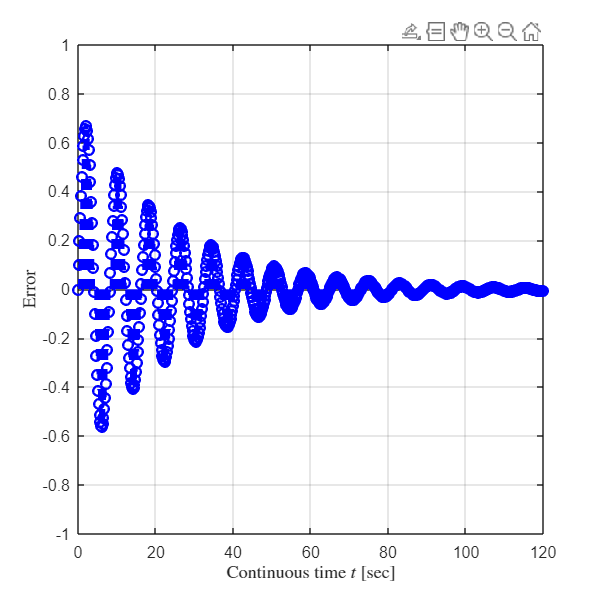

f = figure();
f.Position = [100 100 500 500];
stem(time_dt_sim3,error_sds_sim3,'--b','LineWidth',1.5);
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Error','Interpreter','latex');
xlim([0 T_sim]); 
ylim([-1 1]);